# **Ejercicio 4**

## T5.4 Polinomio de interpolación de Newton

#### Grupo 8: Ana Robledano Abasolo, Alfredo Robledano Abasolo, 

#### Melani Tatayo Culchas, Rubén Sierra Serrano

a) Escribe una función de MATLAB que interpole unos puntos dados utilizando el polinomio de Newton. Nómbrala:

`Yint` `=` `NewtonINT(x,y,Xint)`

La entrada de la función deben ser las coordenadas de los puntos de datos dados en dos vectores `x` e `y` y la coordenada `Xint` del punto en el que se va a interpolar. La salida de la función es el valor `Yint` del punto interpolado. Sugerencia: Inicia el programa calculando las primeras diferencias divididas, que luego se utilizan para calcular las diferencias divididas superiores. Asigna los valores a una matriz. Los coeficientes del polinomio (primera fila de la matriz) se asignan entonces a un vector.

b) Dado el siguiente conjunto de puntos:

Emplea la función creada anteriormente para obtener el valor para $x=3$. Representa gráficamente el polinomio y los puntos interpolados

Preparamos el entorno de trabajo

clear
clc
close all

Zona de declaración de variables

x = [0 1 2 5.5 11 13 16 18];
y = [0.5 3.134 5.3 9.9 10.2 9.35 7.2 6.2];
Xint = 3;

Llamamos a la función y mostramos el resultado

Yint = NewtonINT(x,y,Xint);
fprintf("El punto de interpolación obtenido en x = 3 toma el valor: %.3f",Yint)

El punto de interpolación obtenido en x = 3 toma el valor: 7.072

Acomodamos los vectores para poder representar gráficamente el polinomio de interpolación 

xx = linspace(min(x),max(x));
yy = zeros(size(xx));
for i=1:length(xx)
    yy(i) = NewtonINT(x,y,xx(i));
end

Representación gráfica

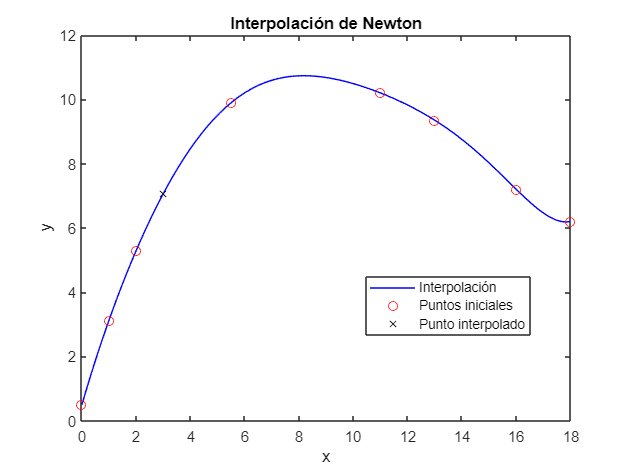

plot(xx,yy,"b-",x,y,"ro",Xint,Yint,"kx");
legend("Interpolación","Puntos iniciales","Punto interpolado","Location","best");
xlabel("x");
ylabel("y");
title("Interpolación de Newton");